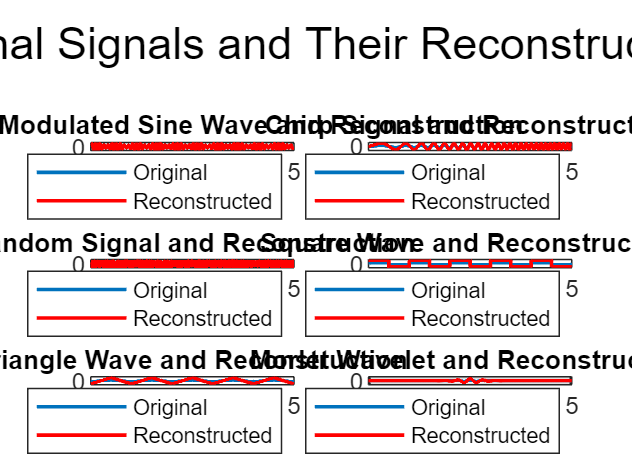

% Parameters
duration = 5;           % Signal duration in seconds
fs = 1000;              % Sampling frequency in Hz

% Time vector
t = 0:1/fs:duration;

% Parameters for the Gaussian curve
sigma = 10;     % Standard deviation

% Generate amplitude-modulated sine wave
carrier_frequency = 10;         % Carrier frequency in Hz
modulation_frequency = 2;      % Modulation frequency in Hz
amplitude_modulated_signal = sin(2*pi*carrier_frequency*t) .* (1 + 0.5*sin(2*pi*modulation_frequency*t));

% Generate chirp signal
f0 = 0.5;                % Initial frequency in Hz
f1 = 10;                % Final frequency in Hz
chirp_signal = sin(2*pi * (f0 + (f1 - f0) ./ (2*duration) .* t) .* t);

% Generate random signal
random_signal = randn(size(t));

% Generate square wave
square_wave = square(2*pi*1*t); % 1 Hz square wave

% Generate triangle wave
triangle_wave = sawtooth(2*pi*1*t, 0.5); % 1 Hz triangle wave

% Generate Morlet wavelet
morlet_wavelet = morlet(-10, 10, 5001); % Morlet wavelet with frequency 1

% Multiply the signal by Gaussian PDF and perform FFT and IFFT

result1 = reconstructSignal(amplitude_modulated_signal, window, 1, fs, duration);
result2 = reconstructSignal(chirp_signal, window, 1, fs, duration);
result3 = reconstructSignal(random_signal, window, 1, fs, duration);
result4 = reconstructSignal(square_wave, window, 1, fs, duration);
result5 = reconstructSignal(triangle_wave, window, 1, fs, duration);
result6 = reconstructSignal(morlet_wavelet, window, 1, fs, duration);

% Plot original and reconstructed signals on the same grid
figure;

% Subplot 1: Amplitude-Modulated Sine Wave
subplot(3, 2, 1);
plot(t, amplitude_modulated_signal, 'LineWidth', 1.2);
hold on;
plot(t(1:end-1), result1, 'r', 'LineWidth', 1.2);
hold off;
title('Amplitude-Modulated Sine Wave and Reconstruction');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Reconstructed');
grid on;

% Subplot 2: Chirp Signal
subplot(3, 2, 2);
plot(t, chirp_signal, 'LineWidth', 1.2);
hold on;
plot(t(1:end-1), result2, 'r', 'LineWidth', 1.2);
hold off;
title('Chirp Signal and Reconstruction');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Reconstructed');
grid on;

% Subplot 3: Random Signal
subplot(3, 2, 3);
plot(t, random_signal, 'LineWidth', 1.2);
hold on;
plot(t(1:end-1), result3, 'r', 'LineWidth', 1.2);
hold off;
title('Random Signal and Reconstruction');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Reconstructed');
grid on;

% Subplot 4: Square Wave
subplot(3, 2, 4);
plot(t, square_wave, 'LineWidth', 1.2);
hold on;
plot(t(1:end-1), result4, 'r', 'LineWidth', 1.2);
hold off;
title('Square Wave and Reconstruction');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Reconstructed');
grid on;

% Subplot 5: Triangle Wave
subplot(3, 2, 5);
plot(t, triangle_wave, 'LineWidth', 1.2);
hold on;
plot(t(1:end-1), result5, 'r', 'LineWidth', 1.2);
hold off;
title('Triangle Wave and Reconstruction');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Reconstructed');
grid on;

% Subplot 6: Morlet Wavelet
subplot(3, 2, 6);
plot(t, morlet_wavelet, 'LineWidth', 1.2);
hold on;
plot(t(1:end-1), result6, 'r', 'LineWidth', 1.2);
hold off;
title('Morlet Wavelet and Reconstruction');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original', 'Reconstructed');
grid on;

% Increase the height of the y-axis for Subplot 6
new_ylim6 = get(gca, 'YLim') * 2; % Adjust the multiplier as needed
ylim(new_ylim6);

% Adjust layout
sgtitle('Original Signals and Their Reconstructions');

function reconstruction = reconstructSignal(signal, window, sigma, fs, duration)
% reconstructSignal Reconstructs a signal using Gaussian windowing
%   reconstructedSignal = reconstructSignal(signal, window, sigma, fs, duration)
%   applies a Gaussian window to the input signal, performs FFT and IFFT,
%   and reconstructs the signal over the specified duration.
%
% Inputs:
%   - signal: The input signal to be reconstructed
%   - window: The window size in seconds
%   - sigma: The standard deviation of the Gaussian window
%   - fs: The sampling frequency
%   - duration: The total duration of the signal to reconstruct in seconds
%
% Outputs:
%   - reconstructedSignal: The reconstructed signal

% Preallocate array to store the reconstructed signal
reconstruction = zeros(1, duration * fs);

% Time vector for the entire signal
t = (0:length(signal)-1) / fs;

% Loop over the signal in steps of window size
for i = window:2*window:duration
    % Shift mean of distribution
    mu = i;
    
    % Custom Gaussian PDF
    gaus = 10 * exp(-(t - mu).^2 / (2 * sigma^2)) / (sigma * sqrt(2 * pi));
    
    % Apply Gaussian PDF to the signal
    windowed_signal = signal .* gaus;
    
    % Perform FFT with correct number of points
    fft_result = fft(windowed_signal);%, 2*window*fs);

    % Perform IFFT
    ifft_result = ifft(fft_result);

    ind1 = ((i - window)*fs) + 1;
    ind2 = ind1 + (2*window*fs) - 1;
    
    % Add IFFT to reconstruction vector
    reconstruction(ind1:ind2) = reconstruction(ind1:ind2) + ifft_result(ind1:ind2);
end
end